% 2024-5-28 22:29:39
% PNAS_Loop_energy
lpd = 1; % nm, persistence length in defective region

Set up for excitation energy

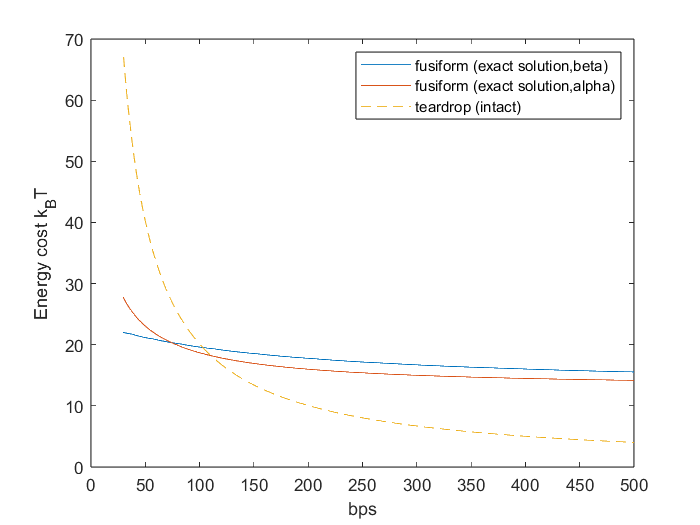


T= 37; %°C
rhos = 0.15;% M salt concentration
lp = cal_Lp(rhos,T,'randome sequence'); % nm, persistence length

j1=1;
N = 30:1:500;
collect_min = zeros(2,length(N));

for Ni = N
    collect_min(1,j1)= cal_E_with_alpha(Ni,lp,lpd,rhos,T);
    collect_min(2,j1)= cal_E_with_beta(Ni,lp,lpd,rhos,T);
j1=j1+1;
end
figure
plot(N,collect_min(1,:))
hold on
plot(N,collect_min(2,:))
a=0.34;
l = N'*a;
D=l/pi;
beta = 2.35;
Edm = 0.5*1/0.34*(2*pi-2*beta-25/180*pi)^2;
% plot(N,Ed+Edm+0.2*2*pi*lp./D);
E_circle = @ (D) 2*pi*lp./D ;
E_kink0_simple = @(D) 0.7953*E_circle(D);
plot(N,E_kink0_simple(D),'--');
xlabel("bps")
ylabel('Energy cost k_BT')
legend('fusiform (exact solution,beta)','fusiform (exact solution,alpha)','teardrop (intact)')

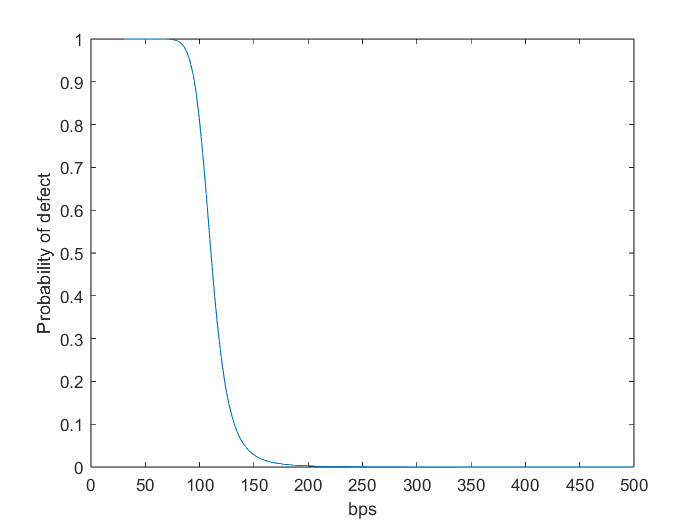




figure
collect_min_2 =min(collect_min);
 energy_reduce = -E_kink0_simple(D)' +collect_min_2;
p_d = 1./(1+exp(energy_reduce));
plot(D*pi/0.34,p_d);
xlabel('bps')
ylabel('Probability of defect')

[~,pos_005]=min(abs(p_d -0.05),[],2);
[~,pos_050]=min(abs(p_d -0.50),[],2);
[~,pos_095]=min(abs(p_d -0.95),[],2);
disp("bps with Probability of defect 5% 50% 95%")

bps with Probability of defect 5% 50% 95%


[D(pos_005)*pi/0.34,D(pos_050)*pi/0.34,D(pos_095)*pi/0.34]

ans =   142.0000  110.0000   91.0000


function z = cal_Lp(x,y,seq)
switch seq
    case 'AT'
        deltaLp = 0;
    case 'AA'
        deltaLp = 0.1861;
    case 'CC'
        deltaLp = 2.7394;
    case 'CG'
        deltaLp = 3.1523;
    otherwise
        deltaLp = 1.4144;
end
z0 = 103.30595;
A01 = 1675.90662;
B01 =2.33204;
B02 = -0.05664;
C02 = 16.56576;
A1=43.96117;
A2=-0.92873;
B1=0.04154;
B2=-0.0012;
C2=0.6008;

z = (z0 + A01*x + B01*y + B02*y.^2 + C02*x.*y)./ ...
(1 + A1*x + B1*y + A2*x.^2 + B2*y.^2 + C2*x.*y)+deltaLp;

end

function min_val = cal_E_with_alpha(N,Lp,lpd,salt,T)
lp=50; %nm
lpd=1;
salt = 0.15;%M
T = 37; %C
Ed= 8.7/(49.2*salt+1)-T*0.11+15.9;
a=0.34;
l = N'*a;
theta0 = 25/180*pi;

E_kink2 = @(alpha,beta,l,lpd) 2*lp./l.*(beta-alpha).*(beta-alpha+(sin(alpha)-sin(beta))./cos(alpha))...
+0.5*lpd/a.*(-theta0+2*pi-2*beta).^2+Ed;  
% +0.5*lpd/a.*(2*alpha-theta0).^2+Ed;    

alpha = 0:0.01:pi/2-0.1;
beta = pi/2:0.1:pi;
E_f = E_kink2(alpha,beta',l,lpd);

[min_val, idx] = min(E_f(:));
end

function min_val = cal_E_with_beta(N,Lp,lpd,salt,T)
lp=50; %nm
lpd=1;
salt = 0.15;%M
T = 37; %C
Ed= 8.7/(49.2*salt+1)-T*0.11+15.9;
a=0.34;
l = N'*a;
theta0 = 25/180*pi;

E_kink2 = @(alpha,beta,l,lpd) 2*lp./l.*(beta-alpha).*(beta-alpha+(sin(alpha)-sin(beta))./cos(alpha))...
 +0.5*lpd/a.*(2*alpha-theta0).^2+Ed; 
%+0.5*lpd/a.*(-theta0+2*pi-2*beta).^2+Ed;  
%   

alpha = 0:0.01:pi/2-0.1;
beta = pi*2/3:0.1:pi;
E_f = E_kink2(alpha,beta',l,lpd);

[min_val, idx] = min(E_f(:));
end